clc; clearvars; close all;

fprintf('▶ Testing trajectory planner (base + arm)...\n');

▶ Testing trajectory planner (base + arm)...



   MOBILE MANIPULATOR TRAJECTORY TEST SUITE

[TEST] quintic_bc...
  ✔ quintic_bc PASSED.

[TEST] mm_planner_arm_quintic...


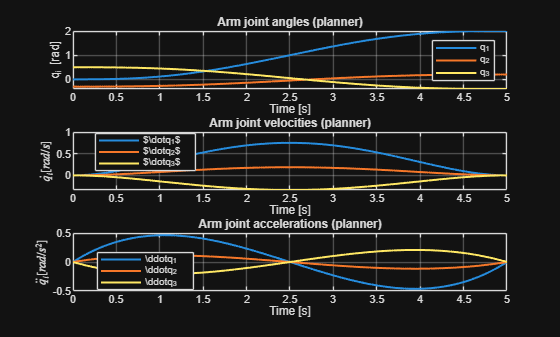

  ✔ arm planner PASSED.

[TEST] mm_planner_base_se2_geodesic...


Error using assert
Assertion failed.

Error in mm_test_planner_suite>test_planner_base_se2_geodesic (line 171)
    assert(norm([refF.x; refF.y; refF.theta] - traj.pf) < 1e-6);
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^


%% 1) Paths & parameters
project_root = './';

addpath(fullfile(project_root, 'test_cases'));

mm_test_planner_suite(true);